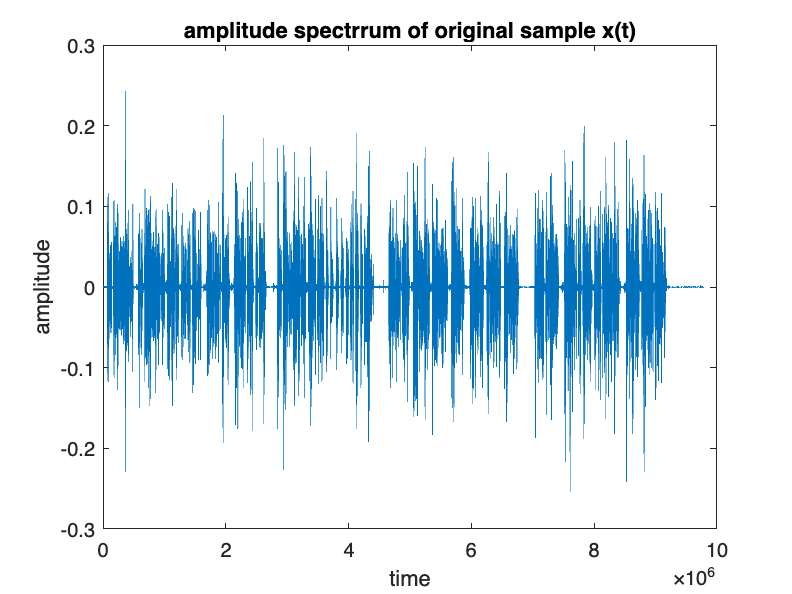

close all
clear x Fs

% load sample
sample = './samples/input/MusArch_Sample_96kHz_AnechoicSpeech.wav';
[x,Fs] = audioread(sample);
x = sum(x,2)/2; % set it mono
len_x = length(x); % set sample length

% plot amplitude spectrum of original sample
plot(x);
xlabel("time");
ylabel("amplitude");
title("amplitude spectrrum of original sample x(t)");

% define filter
filterIn = x;
octFiltBank = octaveFilterBank('SampleRate', Fs, FrequencyRange=[18 22000]);

% visualize filters magnitude response
fvt = fvtool(octFiltBank,"NFFT",2^16);
set(fvt,FrequencyScale="log");
zoom(fvt,[.01 24 -20 1]);

% center freq. of each filter
fc = getCenterFrequencies(octFiltBank);
cf = string(size(fc));
for ii = find(fc<1000)
    cf(ii) = sprintf("%.0f Hz",round(fc(ii),2,"significant"));
end
for ii = find(fc>=1000)
    cf(ii) = sprintf("%.1f kHz",fc(ii)/1000);
end
disp(cf); % center freq. of each filter

    "32 Hz"    "63 Hz"    "130 Hz"    "250 Hz"    "500 Hz"    "1.0 kHz"    "2.0 kHz"    "4.0 kHz"    "7.9 kHz"    "15.8 kHz"



% filtering
filterOut = octFiltBank(filterIn);
[N, numFilters, numChannels] = size(filterOut);

disp(N);

     9779200



disp(numFilters);

    10



disp(numChannels);

     1



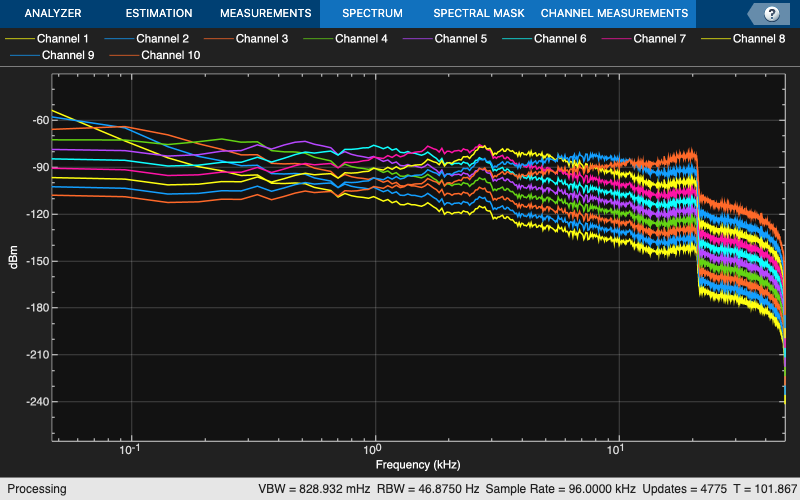


% spectrum analizer
sa = spectrumAnalyzer(SampleRate=Fs, PlotAsTwoSidedSpectrum=false, FrequencyScale="log");
sa(filterOut);


% conpensate group delays
groupDelay = round(getGroupDelays(octFiltBank)); % round for simplicity
filterPadded = [filterOut;zeros(max(groupDelay), numFilters, numChannels)];
for i = 1 : numFilters
    filterOut(:,i,:) = filterPadded(groupDelay(i)+1:N+groupDelay(i), i, :);
end


% audio export of each channels
for i = 1 : numFilters
    audiowrite('./samples/output/filterOut' + string(i) + '.wav', filterOut(:,i,:), Fs);
end

% reconstruct original signal
reconstructedAudio = squeeze(sum(filterOut, 2));
reconstructedAudio = reconstructedAudio/max(abs(reconstructedAudio(:)));
audiowrite('./samples/output/reconstractAudio.wav', reconstructedAudio, Fs); % notice: the output siganl is monoral